clear all; clc;

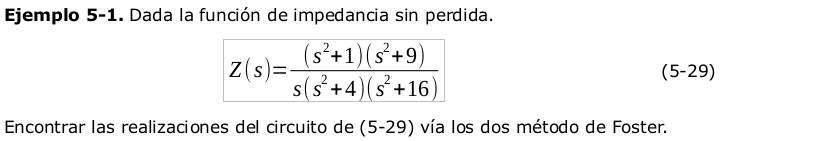


syms s p 'real'
Z(s) = ((s^2 +1)*(s^2 +9))/(s*(s^2 +4)*(s^2 +16))

 
Z(s) =
 
((s^2 + 1)*(s^2 + 9))/(s*(s^2 + 4)*(s^2 + 16))
 



% cambio de variable s^2 por p
Z(p)=subs(Z(s)/s,s^2,p);

% extraigo el polinomio numerador y denominador
[n,d]=numden(Z(p));

% ordeno con collect y extraigo los coeficientes.
b=sym2poly(collect(n));
a=sym2poly( collect(d));

[r,po,k]=residue(b,a);

% construyo la expresión con fracciones parciales
Zf(p)=sym('0');
for n=1:length(r)
   Zf(p)=Zf(p)+r(n)/(p-po(n));
end

%pretty(Zf(p))

% cambio de variables p por s^2
Z(s)=subs(Zf(s)*s,p,s^2);

pretty(expand(Z(s),'ArithmeticOnly',true))

0.3125 s   0.5469 s
-------- + -------- + 0.1406
  s + 4     s + 16

